Data

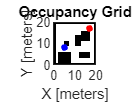


%Lidar setup
lidar = rangeSensor;
%VFH setup
vfh = controllerVFH;
vfh.UseLidarScan = true;
vfh.SafetyDistance = 0.5;
%vfh.DistanceLimits = [1 2];

%We show it to see our first part
MapFigure = figure;
VFHFigure = figure;
figure(MapFigure);
show(Map)
hold on
plot(robot_pose(1), robot_pose(2), 'bo', 'MarkerSize', 2, 'LineWidth', 2);
plot(goal_pose(1), goal_pose(2), 'bo', 'MarkerSize', 2, 'LineWidth', 2, 'Color',"red");


allVFHdata = [];

x = 0;
trigger = true

trigger = logical
   1


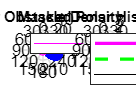

while trigger
    %Lidar measures
    [ranges,angles] = lidar(robot_pose,Map);


    %Geometry about the angles the be appropriate
    %We calculate the Eucladean distance between the start and end coordinates
    tavolsag_x = goal_pose(1) - robot_pose(1);
    tavolsag_y = goal_pose(2) - robot_pose(2);

    %We use the atan2d to get back the corresponding angle that is in the four
    %quadrant
    goal_angle = atan2d(tavolsag_y,tavolsag_x);
    %We make a correction with the original orientation of the UAV
    goal_angle= deg2rad(goal_angle)+deg2rad(0-start_orientation);
    %We scan the virtual environment
    scan = lidarScan(ranges,angles);
    %We rotate it to be according to the drone orientation
    rotateScan = transformScan(scan,[0,0,robot_pose(3)+deg2rad(0-start_orientation)]);

    %Use the VFH algorithm to calculate the required steering angle in rad
    steeringDir = vfh(rotateScan,goal_angle);
    %Convert it to deg
    new_deg = rad2deg(steeringDir);
    figure(VFHFigure)
    show(vfh)

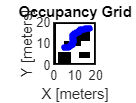

trigger = logical
   0


    %Drone parameter setup
    v_drone = 0.2; %m/s [currently be at 0.2, later we can do dynamic adjustments]

    robot_pose(3) = new_deg;
    robot_pose(1) = robot_pose(1)+cosd(new_deg)*v_drone;
    robot_pose(2) = robot_pose(2)+sind(new_deg)*v_drone;
    allVFHdata = [allVFHdata; robot_pose(1), robot_pose(2)];
    figure(MapFigure);
    plot(robot_pose(1), robot_pose(2), 'bo', 'MarkerSize', 2, 'LineWidth', 2);
    drawnow
    x = x+1;
    
    if abs(tavolsag_x) < 0.4 && abs(tavolsag_y) < 0.3
        trigger = false
    end

end


allVFHdata

allVFHdata =     5.1995    8.0142
    5.3990    8.0285
    5.5985    8.0427
    5.7980    8.0569
    5.9975    8.0712
    6.1970    8.0854
    6.3964    8.0997
    6.5959    8.1139
    6.7948    8.1351
    6.9904    8.1769
